clc ; clear all ; close all ; 

% Read the image
inputImage = imread("D:\IMAGES\ORION\pipp_20240331_003120\_MG_0082\_MG_0047.tif");  % Replace with your image file path

% Separate the color channels
redChannel = inputImage(:, :, 1);
greenChannel = inputImage(:, :, 2);
blueChannel = inputImage(:, :, 3);

% Step 1: Apply CLAHE to each color channel
claheRed = adapthisteq(redChannel, 'ClipLimit', 1, 'NumTiles', [2 2]); % Adjust ClipLimit if needed
claheGreen = adapthisteq(greenChannel, 'ClipLimit', 1, 'NumTiles', [2 2]);
claheBlue = adapthisteq(blueChannel, 'ClipLimit', 1, 'NumTiles', [2 2]);

claheRed1 = adapthisteq(claheRed, 'ClipLimit', 1, 'NumTiles', [2 2]); % Adjust ClipLimit if needed
claheGreen1 = adapthisteq(claheGreen, 'ClipLimit', 1, 'NumTiles', [2 2]);
claheBlue1 = adapthisteq(claheBlue, 'ClipLimit', 1, 'NumTiles', [2 2]);

claheRed2 = adapthisteq(claheRed1, 'ClipLimit', 1, 'NumTiles', [2 2]); % Adjust ClipLimit if needed
claheGreen2 = adapthisteq(claheGreen1, 'ClipLimit', 1, 'NumTiles', [2 2]);
claheBlue2 = adapthisteq(claheBlue1, 'ClipLimit', 1, 'NumTiles', [2 2]);

% Step 2: Apply Gaussian filter on each CLAHE-enhanced color channel
sigma = 2;  % Adjust sigma for Gaussian filtering
filteredRed = imgaussfilt(claheRed2, sigma);
filteredGreen = imgaussfilt(claheGreen2, sigma);
filteredBlue = imgaussfilt(claheBlue2, sigma);

% Step 3: Apply gamma correction on each filtered color channel
gammaValue = 3;  % Adjust gamma value if needed
gammaCorrectedRed = imadjust(filteredRed, [], [], gammaValue);
gammaCorrectedGreen = imadjust(filteredGreen, [], [], gammaValue);
gammaCorrectedBlue = imadjust(filteredBlue, [], [], gammaValue);

% Recombine the color channels
outputImage = cat(3, gammaCorrectedRed, gammaCorrectedGreen, gammaCorrectedBlue);

imshow(outputImage); title('CLAHE + Gaussian Filter + Gamma Correction on RGB Channels');

% Read the input image
inputImage1 = outputImage ; % Replace with your image file path

% Convert the image to double for processing
inputImageDouble = im2double(inputImage1);

% Separate the color channels
redChannel1 = inputImageDouble(:, :, 1);
greenChannel1 = inputImageDouble(:, :, 2);
blueChannel1 = inputImageDouble(:, :, 3);

% Remove periodic noise from each channel
filteredRed = removePeriodicNoise(redChannel1);
filteredGreen = removePeriodicNoise(greenChannel1);
filteredBlue = removePeriodicNoise(blueChannel1);

% Recombine the filtered channels
finalImage = cat(3, filteredRed, filteredGreen, filteredBlue);
imshow(finalImage); title('Image after Noise Removal');

c = 2; % Scaling constant (adjust based on desired brightnesse)
log_img1 = c * log(1 + im2double(finalImage));
imshow(log_img1);

image_double = im2double(log_img1);
gamma = 0.6;

% Apply gamma correction to each channel (R, G, B)
corrected1_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected1_image);

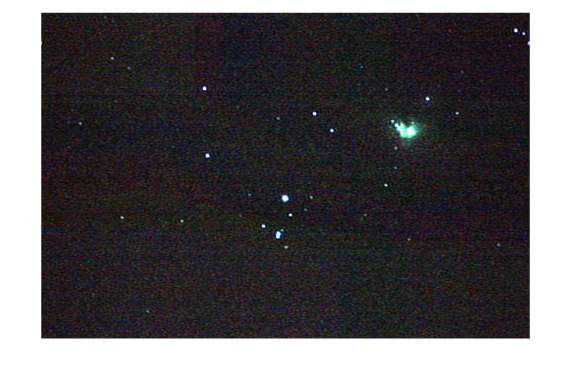

title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

% Assume corrected1_image is your processed image
imwrite(corrected1_image, 'corrected1_image.tif');  % Save as JPEG format


function filteredChannel = removePeriodicNoise(channel)
    % Apply FFT
    fftChannel = fft2(channel);
    fftShifted = fftshift(fftChannel);  % Shift zero frequency components to the center

    % Create a low-pass filter (you can customize this filter)
    [rows, cols] = size(channel);
    crow = round(rows/2);
    ccol = round(cols/2);
    radius = 130;  % Adjust the radius to define the cutoff frequency

    [X, Y] = meshgrid(1:cols, 1:rows);
    D = sqrt((X - ccol).^2 + (Y - crow).^2);  % Distance from the center

    % Create a circular low-pass filter
    H = double(D <= radius);

    % Apply the filter
    filteredFFT = fftShifted .* H;

    % Inverse FFT to convert back to spatial domain
    filteredChannel = ifft2(ifftshift(filteredFFT));
    filteredChannel = real(filteredChannel);  % Take the real part
end